%This file calls pair5.m, which is where the main trading strategy is
%located. If you run this, you should be able to get trading results. Make
%sure your current folder is the folder that contains the .mat files. 

clear
clc
load SPX218.mat

Error using load
'SPX218.mat' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\lijin\Google Drive\PRMC\PairsTrading\Data

Change the MATLAB current folder or add its folder to the MATLAB path.

load SPX218industry.mat
load coStocks.mat

[numDays, numStocks] = size(SPX218);
numStocks = numStocks - 1;

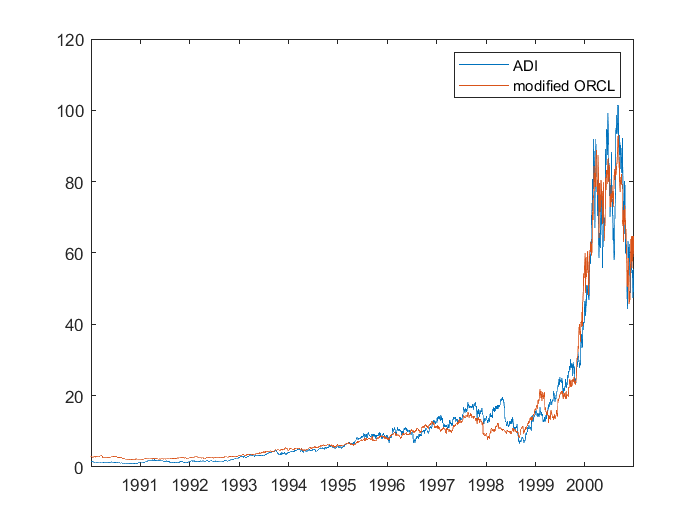

Stock1 = 5;
Stock2 = 156;
series = [SPX218{:, Stock1+1} SPX218{:, Stock2+1}];
[~,~,stat0,~,reg0] = egcitest(series);
x = (1:numDays)';
clf
plot(SPX218{:,1}, series(:,1))
hold on
plot(SPX218{:,1}, (series(:,2)*reg0.coeff(2)+reg0.coeff(1)))
Stock1Name = cell2mat(SPX218(:,Stock1+1).Properties.VariableNames);
Stock2Name = cell2mat(SPX218(:,Stock2+1).Properties.VariableNames);
legend(Stock1Name, "modified " +Stock2Name);
hold off

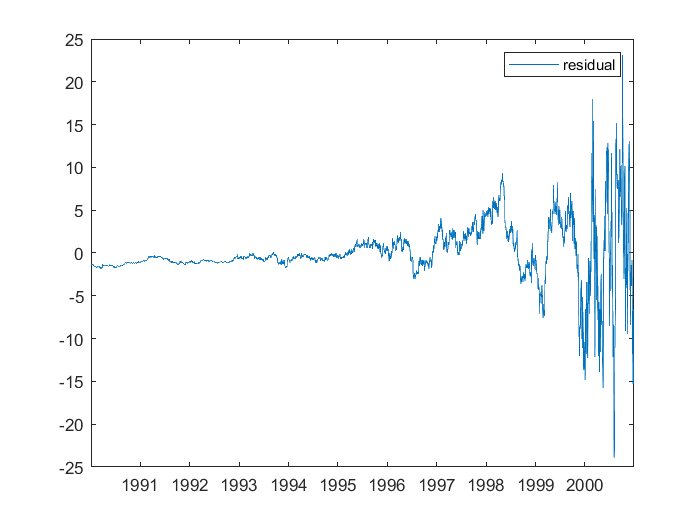

coSeries = series(:,1)-(series(:,2)*reg0.coeff(2)+reg0.coeff(1));
plot(SPX218{:,1}, coSeries)
legend("residual");

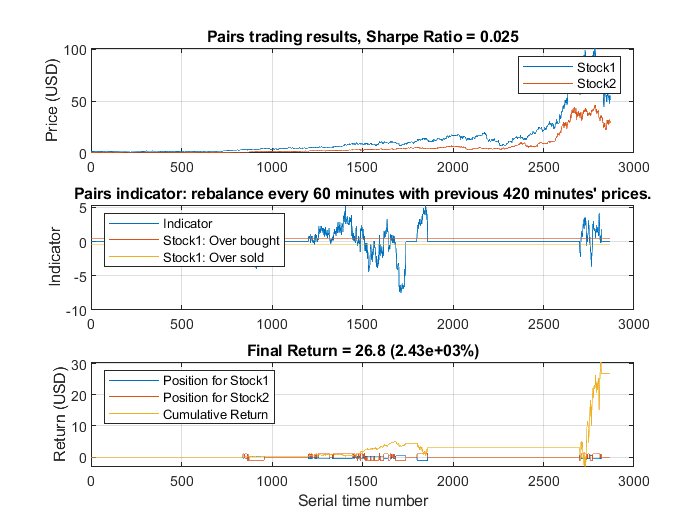

pairs2(series)

clear selectedPairs

numPairs = 20;
selectedPairs = coStocks(1:numPairs, 2:5);

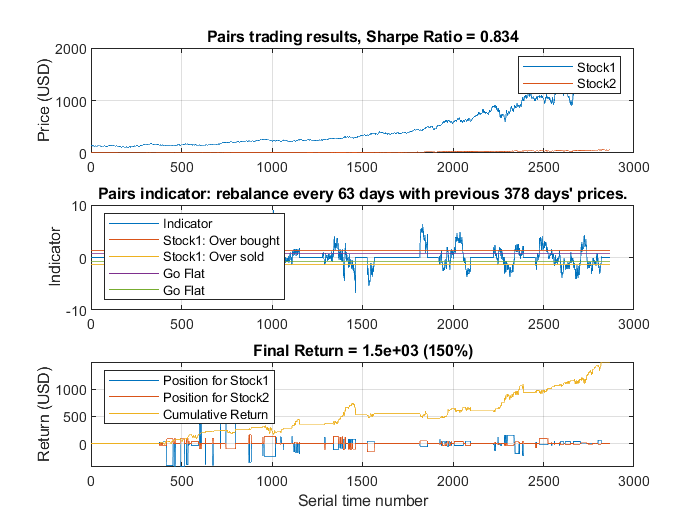

a1 = 0.3495

a2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


a3 = 0.8341

a4 = -0.0395

result0 = 	1.0e+03 *

    0.1490    0.0054         0         0         0         0         0         0         0         0         0    1.0000
    0.1488    0.0055         0         0         0         0         0         0         0         0         0    1.0000
    0.1467    0.0055         0         0         0         0         0         0         0         0         0    1.0000
    0.1423    0.0055         0         0         0         0         0         0         0         0         0    1.0000
    0.1414    0.0054         0         0         0         0         0         0         0         0         0    1.0000
    0.1405    0.0053         0         0         0         0         0         0         0         0         0    1.0000
    0.1400    0.0052         0         0         0         0         0         0         0         0         0    1.0000
    0.1401    0.0053         0         0         0         0         0         0         0         0         0    1.0000
    0.1366

clf
tic
[a1,a2,a3,a4,result0]=pairs5(SPX218, selectedPairs)

toc

Elapsed time is 50.032437 seconds.


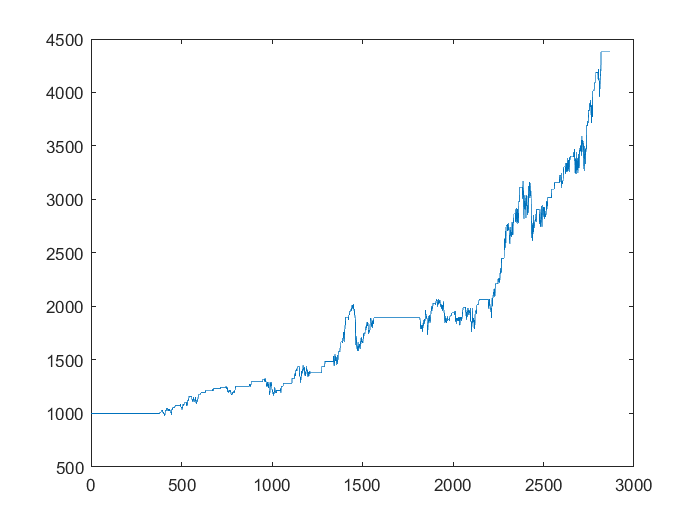

clf
plot(result0(:,12))